# Modeling and Optimizing a Battery Charging Profile

In this script, we will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

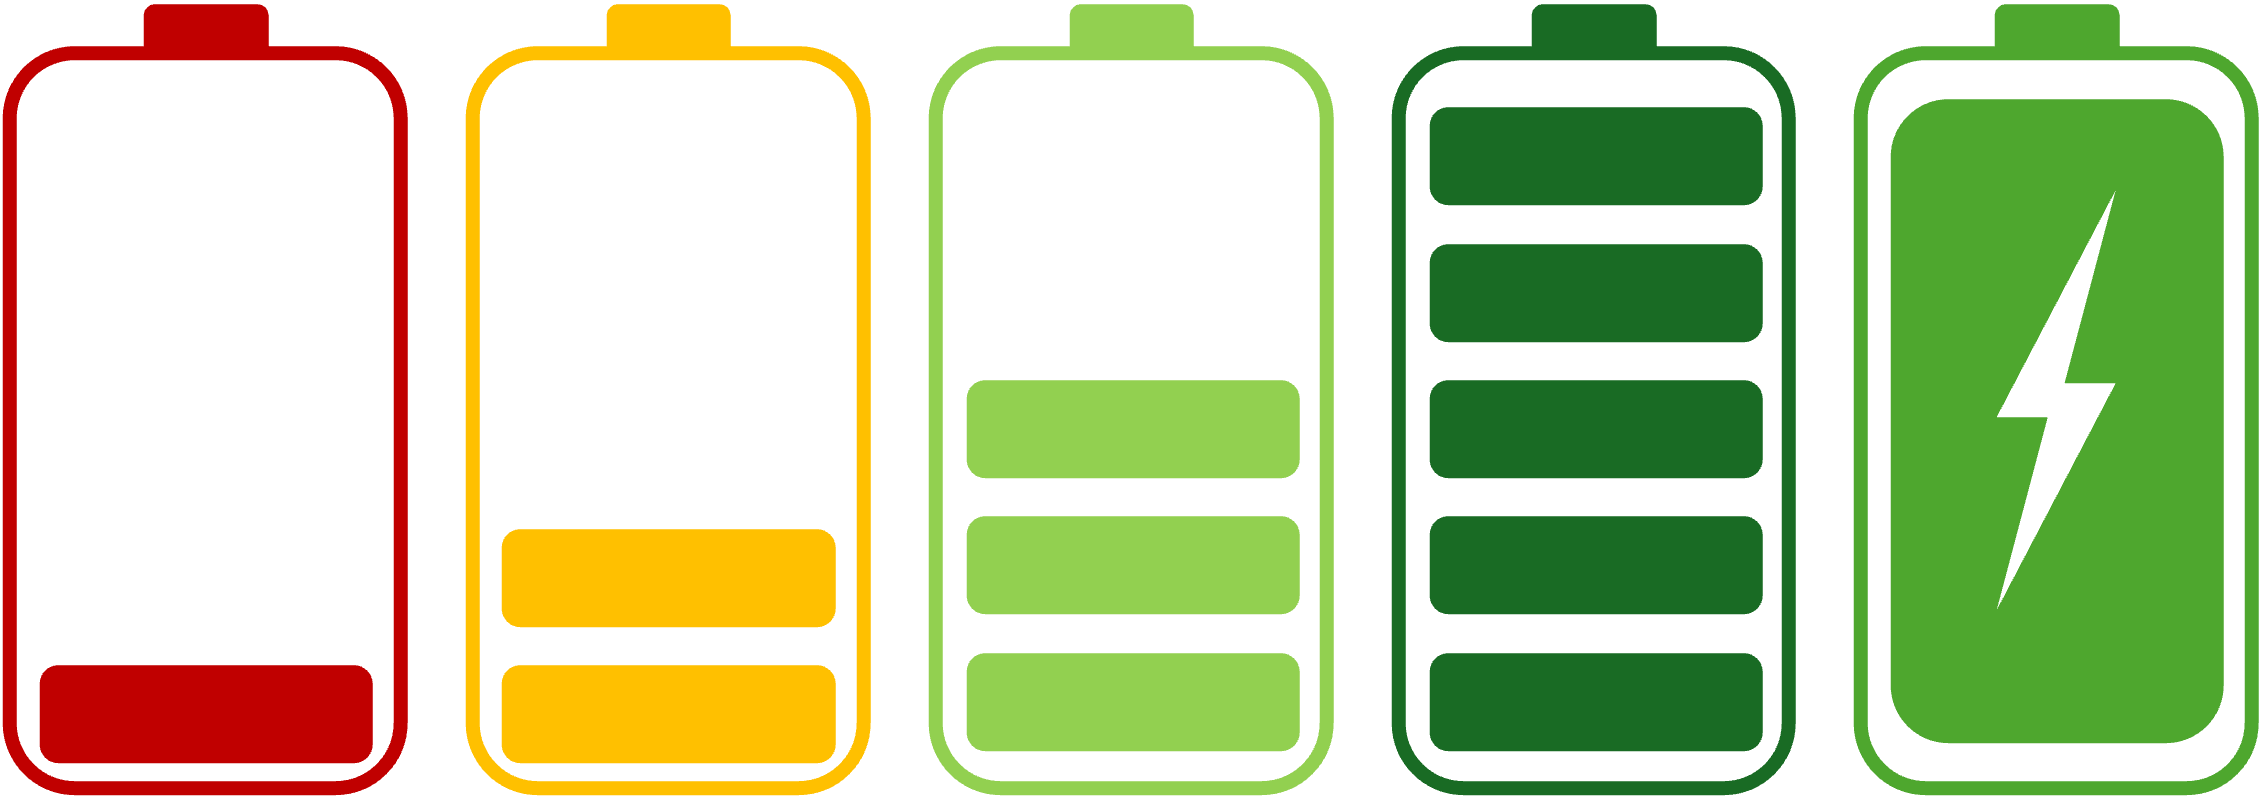

## Break Down the Problem

**Problem Statement:**

Model and analyze the charging profile of a lithium-ion battery using real-world data. We need to use MATLAB to mathematically fit a specific voltage equation to the provided battery data, visualize the electrical characteristics over time, and apply numerical methods (integration and differentiation) to compute key performance metrics like total energy transfer, charging rates, time-to-charge, and efficiency losses due to resistance.

**List the requirements, constraints, and success criteria for the project:**

- **Requirements:**

- Must use MATLAB to perform all calculations and modeling.

- Fit the given voltage equation to the provided lithium-ion battery data.

- Generate three specific plots: voltage vs. time, current vs. time, and power vs. time.

- Use numerical integration to compute total energy delivered (area under the power-time curve).

- Calculate derivatives to analyze the rate of voltage change across different charging intervals.

- Determine the exact time it takes to reach 80% and 100% charge states.

- Compute the energy lost due to internal resistance.

- **Constraints:**

- The model must be built upon the specific dataset and voltage equation provided in the broader Project Description.

- Calculations for energy and rates of change must rely on numerical methods applied to the provided discrete data points.

- **Success Criteria:**

- A MATLAB script that successfully runs without errors and performs the necessary curve fitting.

- Clear, accurately labeled plots for voltage, current, and power over time.

- Accurate final computed values for total energy delivered, time to 80%/100% charge, and energy loss.

**What is your proposed solution?**

The proposed methodology involves the development of a structured MATLAB Live Script to systematically analyze the empirical battery dataset. Initially, the time-series data will be imported into the MATLAB workspace, and the Curve Fitting Toolbox will be utilized to model the theoretical RC-circuit voltage equation against the experimental charging data. Following the curve fit, an instantaneous power array will be derived by computing the product of the voltage and current vectors at each discrete time interval.

To evaluate the battery's performance characteristics, visual representations of the voltage, current, and power profiles will be generated. Subsequently, numerical methods will be applied to extract key metrics: trapezoidal numerical integration (`trapz`) will be employed on the power array to quantify the total energy transfer, while numerical differentiation (`diff`) will be utilized to determine the instantaneous rate of voltage change across distinct charging phases. These computational techniques will facilitate the precise determination of time-to-charge thresholds (80% and 100%) and the quantification of energy dissipation attributed to internal resistance.

**List the steps you will need to take to achieve your proposed solution:**

- **Data Import & Setup:** Load the real lithium-ion battery data into MATLAB workspace variables (extracting time, voltage, and current).

- **Curve Fitting (Task 1):** Define the provided voltage equation and fit it to the real data using MATLAB's regression/curve-fitting functions.

- **Data Calculation:** Compute the electrical power at each time step (Power = Voltage * Current).

- **Visualization (Task 2):** Create a figure with subplots for voltage vs. time, current vs. time, and power vs. time.

- **Integration (Task 3):** Apply numerical integration (e.g., trapezoidal rule) on the power-time data to calculate the total energy delivered.

- **Differentiation (Task 4):** Calculate the derivative of the voltage data with respect to time (dV/dt) to analyze the charge rate at different intervals.

- **Threshold Analysis:** Analyze the data arrays to find the timestamps corresponding to 80% and 100% charge levels.

- **Efficiency Calculation:** Calculate the energy lost to resistance using the current data and the assumed internal resistance values.

**What challenges do you face in the process of achieving the solution?**

- **Data Noise:** Real battery data often contains noise or fluctuations. Fitting a clean mathematical equation to noisy data might require preprocessing or choosing the right fitting tolerances.

- **Numerical Errors:** Numerical integration and differentiation can introduce errors depending on the time-step size of the provided data. Large time gaps between data points could make the derivatives spike unnaturally or make the total energy calculation less accurate.

- **Identifying Charge States:** Accurately determining exactly when the battery hits 80% and 100% charge might be tricky if the data points don't land exactly on those percentages, requiring interpolation.

# Task 1: Fit the voltage equation to a lithium-ion battery profile

**1.1  Objective and success criteria**

Task 1 fits the prescribed first-order RC law to a single measured charge cycle in order to estimate the charging time constant and to establish how far a single-exponential model can represent this cell, which is charged with a multi-step constant-current, constant-voltage (CC-CV) profile rather than from a fixed source voltage. The inputs are elapsed time, terminal voltage and current for one cycle of the MathWorks single-cell lifetime dataset, plus one externally known constant: the 3.6 V full-charge voltage. The outputs are the fitted model, one labelled figure of measurement against model, and the printed goodness-of-fit statistics. Task 1 is complete when:

- the section runs from a cleared workspace and regenerates the figure and the statistics;

- the fit converges to a finite, strictly positive time constant inside the bounds, reported with its 95% confidence interval and the full goodness-of-fit statistics;

- the agreement between the fitted exponential and the measured profile is assessed quantitatively, and each systematic departure is attributed to a specific phase of the CC-CV charging protocol.

**1.2  Where the voltage equation comes from**

The equation is the exact solution of the circuit the cell is modeled as, not a curve chosen because it resembles the data. The charger is treated as a constant voltage source, the ohmic losses of electrolyte, electrodes and connections are lumped into one series resistance, and the charge storage of the cell into one capacitance. Kirchhoff's voltage law around that loop gives $V_{\max } =i\left(t\right)R+V\left(t\right)$, and the current is the rate at which charge reaches the capacitance, $i\left(t\right)=C\frac{dV}{dt}$. Substituting gives a first-order linear ODE,


$$\mathrm{RC}\frac{dV}{dt}+V\left(t\right)=V_{\max }$$


which, separated and integrated with the capacitance initially uncharged, yields the equation to be fitted:


$$V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$$


Physically, the full source voltage stands across the resistance at the start, so charging is fastest then; as the capacitance charges it develops an opposing voltage, leaving only the remaining gap to drive current. The rate of charging is proportional to how much charging is left to do, and that is precisely the condition that produces an exponential rather than any other saturating curve.

The product $\tau =\mathrm{RC}$ is the only time scale present, and it must be a time because the exponent is dimensionless: an ohm is a volt per ampere and a farad a coulomb per volt, so their product is a coulomb per ampere, a second. It is the time to close 63.2% of the gap to the final voltage, and because each interval of one time constant removes the same fraction of whatever gap remains, charging is 99.3% complete after five of them.

**1.3  Parameter Choice & RC omission **

The maximum voltage is fixed at 3.6 V rather than fitted. It is externally known, and fitting an asymptote and a time constant together makes both less certain because they trade off against each other over a record only a few time constants long. In the code it is declared a problem parameter, the Curve Fitting Toolbox term for a value supplied rather than optimized. The resistance and capacitance are not estimated separately because they cannot be: they enter the model only through their product, so voltage data cannot distinguish a large resistance with a small capacitance from the reverse. This is parameter identifiability, not a numerical limitation, and no optimizer resolves it. Only the lumped time constant is estimated, in seconds; if the elements are wanted, the dataset's internal-resistance column gives $C=\tau /R$ afterwards, which is an inference from a second measurement rather than an output of this fit.

**1.4  Why We Use Nonlinear Square Method**

The model is linear in the maximum voltage but nonlinear in the time constant, which sits inside an exponential in a denominator. Its derivative with respect to that parameter still depends on the parameter, so the least-squares condition does not reduce to linear normal equations and there is no closed-form solution. The residual sum of squares


$$S\left(\tau \right)=\sum_{i=1}^N {\left(V_i -V_{\max } \left(1-e^{-\frac{t_i }{\tau }} \right)\right)}^2$$


must therefore be minimized iteratively, which is what nonlinear least squares does, by default with a trust-region reflective algorithm well suited to a bounded problem. It is also the only admissible choice here: the toolbox restricts linear least squares to models linear in their coefficients, so a custom exponential leaves no alternative.

The tempting shortcut was considered and rejected. Taking logarithms linearizes the model to


$$\ln \left(1-\frac{V}{V_{\max } }\right)=-\frac{t}{\tau }$$


so the time constant could come from the slope of an ordinary linear regression with no iteration. Three objections, in increasing order of seriousness: it minimizes a differently weighted objective than the additive, roughly constant-magnitude voltage noise justifies; it amplifies that noise severely near the asymptote, where most samples of a charge record lie; and it is undefined once any measured sample reaches the assumed maximum, which during a constant-voltage hold at 3.6 V is close to certain rather than a rare edge case. A polynomial or spline would track the data more closely but yields no time constant, so it could not serve as the benchmark Task 3 needs. Nonlinear least squares also accepts bounds, so the requirement that the time constant be positive is enforced rather than hoped for, and it supports a confidence interval on the estimate. Its one cost is dependence on the starting guess, which is why the appendix sweeps it.

**1.5  Implementation**

- **Select one cycle **on the cycle index, so that cell aging does not blend charge profiles recorded at different states of health into a single fit.

- **Keep the charging phase only, **selected on positive current. Two things are worth checking rather than assuming: that the sign convention is as expected, confirmed by the voltage rising across the window, and that the retained samples are contiguous, since a logical filter will silently join charge segments separated by rest periods.

- **Build the time axis **by subtracting the first timestamp and converting to seconds, which puts the origin where the model's initial condition assumes it.

- **Fit **with nonlinear least squares, a 500 s starting guess whose order of magnitude comes from the observed charge duration, and a lower bound just above zero enforcing a positive time constant; the maximum voltage is passed in as the problem parameter.

- **Report **measurement and model on one set of axes with units, then print the goodness-of-fit statistics and the fitted model so the time constant appears in the output.

**1.6  Assumptions and limitations**

- **One resistance and one capacitance. **Real cells relax on several time scales, so a single time constant is a summary rather than a complete description.

- **A constant-voltage source. **This cell is charged with a dynamic constant-current then constant-voltage profile. During the constant-current phase the voltage rises nearly linearly, so systematic disagreement there is expected and is a property of the model rather than a defect in the fit.

- **Zero initial voltage. **False for a battery, which retains a substantial open-circuit voltage when discharged. This is the largest source of bias: the model is pinned to the origin while the measurement starts near three volts, so the optimiser distorts the time constant to compensate.

- **Additive, roughly constant-magnitude voltage noise. **A fair description of voltmeter error, and the condition that makes least squares the appropriate estimator.

The third is imposed by the prescribed equation, not by any choice in the code, and it can be quantified rather than merely noted. Fitting the three-parameter variant


$$V\left(t\right)=V_0 +\left(V_{\max } -V_0 \right)\left(1-e^{-t/\tau } \right)$$


as a sensitivity test, while still reporting the prescribed model as the result, shows how much of the residual that single assumption accounts for. The appendix does this.

**1.7  Validation strategy**

R-squared alone is weak evidence, because any curve that rises and saturates scores well against data that rises and saturates. The checks in the appendix therefore triangulate: an independent hand estimate of the time constant from the 63.2% crossing, which validates the implementation but not the physics since it shares the zero-initial-voltage assumption; a 95% confidence interval, so the estimate is reported as an interval; a residual plot, where structure rather than scatter diagnoses a wrong functional form; a sweep of the starting guess across five decades to confirm the optimum is global rather than local; and explicit edge-case checks that the charge window is non-empty, strictly increasing, free of large gaps, and rising.

The expected outcome is worth stating in advance. Because the cell is charged with a CC-CV profile rather than from a fixed source voltage, the exponential should coincide with the measurement over the constant-voltage plateau and depart from it systematically over the constant-current stages. The residuals should therefore be structured rather than scattered, and the fitted time constant should be interpreted only after it has been checked against the observed duration of the charge.

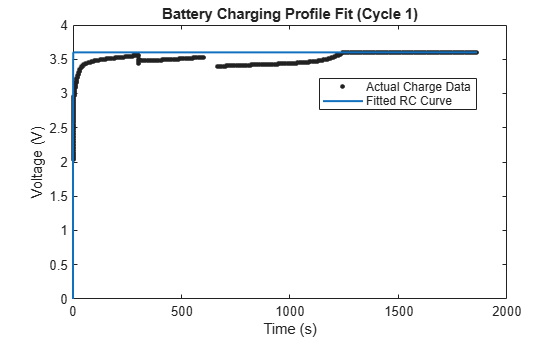

%% Task 1: Modeling the Battery Charging Profile (First-Order RC Circuit)
% This script extracts the first charging cycle from a battery dataset, 
% fits the voltage data to a first-order RC exponential equation, 
% visualizes the fit, and outputs the goodness-of-fit statistics.
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
cycleData = data(data.Cycle_Index == 1, :);

%% Step 1 & 2: Data Extraction and Pre-Processing
% Filter the main dataset to only include data from the first cycle.
cycle1Data = data(data.Cycle_Index == 1, :);

% Isolate the charging phase. 
% We know the battery is charging when the current is positive (> 0).
chargeData = cycle1Data(cycle1Data.Current > 0, :);

% Convert the DateTime timestamps into a numerical array of elapsed seconds.
% We subtract the very first timestamp from all others so our time starts at t = 0.
t_data = seconds(chargeData.DateTime - chargeData.DateTime(1));

% Extract the corresponding voltage readings for the y-axis.
V_data = chargeData.Voltage;

%% Step 3: Set Up the Mathematical Model
% Define the known maximum voltage for this specific lithium-ion battery.
Vmax_val = 3.6; 

% Configure the settings for the curve fitting algorithm.
% - 'Method': We use Nonlinear Least Squares since our equation is exponential.
% - 'StartPoint': An initial guess for 'tau' (the RC time constant) in seconds.
% - 'Lower': Sets a lower boundary so tau doesn't drop to physically impossible values (<= 0).
fo = fitoptions('Method', 'NonlinearLeastSquares', ...
                'StartPoint', 500, ...
                'Lower', 1e-5);

% Define the custom exponential equation: V(t) = Vmax * (1 - e^(-t/tau))
% - 'problem': Indicates Vmax is a known constant we will provide.
% - 'independent': Specifies 't' as our x-axis time variable.
% - 'options': Applies the algorithm rules we just set up above.
ft = fittype('Vmax * (1 - exp(-t/tau))', ...
             'problem', 'Vmax', ...
             'independent', 't', ...
             'options', fo);

% Execute the curve fit. 
% We pass in our time data, voltage data, the equation setup, and the actual Vmax value.
% 'chargeFit' stores the resulting equation; 'gof' stores the accuracy metrics.
[chargeFit, gof] = fit(t_data, V_data, ft, 'problem', Vmax_val);

%% Step 4: Visualize the Data and the Fitted Curve
figure; % Open a new, clean figure window

% Plot the actual raw data points and the smooth fitted curve together
plot(chargeFit, t_data, V_data);

% Add clean, professional labels and a title
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Battery Charging Profile Fit (Cycle 1)');

% Add a legend to differentiate the raw data from the model
legend('Actual Charge Data', 'Fitted RC Curve', 'Location', 'best');


%% Step 5: Display Analytical Results
% Print out the Goodness-of-Fit (GOF) statistics (like R-squared and RMSE)
% to prove the mathematical accuracy of our model.
disp('--- Goodness of Fit (GOF) Statistics ---');

--- Goodness of Fit (GOF) Statistics ---


disp(gof);

           sse: 45.6319
       rsquare: 0.2294
           dfe: 611
    adjrsquare: 0.2294
          rmse: 0.2733




% Print the final fitted equation, which will reveal our estimated 
% value for 'tau' (the RC time constant).
disp('--- Fitted Equation and Estimated Tau ---');

--- Fitted Equation and Estimated Tau ---


disp(chargeFit);

     General model:
     chargeFit(t) = Vmax * (1 - exp(-t/tau))
     Coefficients (with 95% confidence bounds):
       tau =       0.228  (0.2096, 0.2463)
     Problem parameters:
       Vmax =         3.6


**Figure 1. **Measured terminal voltage during the charging phase of cycle 1 (points) with the fitted first-order RC model (line). The measurement shows the three features of a multi-step CC-CV charge: a fast initial rise, constant-current stages separated by downward voltage steps near 300 s and 660 s, and a constant-voltage plateau at 3.6 V from about 1250 s onward. The fitted exponential reaches its 3.6 V asymptote within about one second, so it coincides with the plateau and lies above the constant-current stages.

**1.8  Conclusion**

**Results. **Fitting the prescribed equation to 612 samples of cycle 1, with the maximum voltage held at 3.6 V, returned a time constant of 0.228 s with a 95% confidence interval of 0.210 to 0.246 s. The goodness-of-fit statistics were a sum of squared errors of 45.63 over 611 residual degrees of freedom, R-squared of 0.229, adjusted R-squared of 0.229, and a root-mean-square error of 0.273 V. The model therefore accounts for 23% of the variance in the measured voltage, and the fit converged to a well-bounded parameter well inside the imposed lower limit.

**What the measurement shows. **The charge follows a multi-step CC-CV profile. The terminal voltage rises steeply from about 2.0 V to 3.4 V in the first few seconds, then climbs slowly through a series of constant-current stages. The downward steps of roughly 0.08 V near 300 s and 0.14 V near 660 s occur where the charging current is reduced between stages: the ohmic contribution to the terminal voltage falls immediately with the current, so the measured voltage steps down while the state of charge continues to increase. From about 1250 s the cell is held at a constant 3.6 V, and this constant-voltage plateau accounts for roughly the final third of the samples.

**How the model responds. **The fitted exponential has a single time scale, whereas the measurement contains three distinct regimes. With the asymptote fixed at 3.6 V and the curve constrained to pass through the origin, the time constant is determined almost entirely by the steep initial rise, and the model consequently saturates within about one second. It therefore reproduces the constant-voltage plateau exactly and lies between roughly 0.15 V and 0.2 V above the measurement throughout the constant-current stages. The 0.273 V root-mean-square error is this systematic offset rather than random scatter, and it exceeds the 0.2 V of voltage rise that occurs across the constant-current portion.

**Quantitative assessment. **A time constant of 0.228 s corresponds to 99% completion after five time constants, or about 1.1 s, whereas the measured charge occupies approximately 1900 s. The fitted parameter is therefore a description of the initial voltage step and not of the charge-transfer process. The confidence interval of plus or minus 8% is correspondingly narrow because the early samples determine that step precisely, but it quantifies precision within the assumed model only. Taken with the R-squared of 0.229, the model is quantitatively valid over the constant-voltage phase and quantitatively invalid over the constant-current phases.

**Conclusion. **A first-order RC analog is the exact solution for charging from a fixed source voltage, which corresponds to only one of the three regimes present in this record. The model reproduces the constant-voltage plateau and the initial ohmic step, and does not represent the constant-current stages, which is why the fitted time constant characterises the initial step rather than the full charge. The measured profile is described within 0.273 V by a single-exponential model whose valid range is the constant-voltage portion of a CC-CV charge.

# Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

**2.1  Objective and success criteria**

Task 2 visualizes how energy moves through the cell by plotting the three electrical quantities that describe it, voltage, current and power, across one complete charge and discharge cycle, and then isolates the charging phase so that the model fitted in Task 1 can be laid over the data it was fitted to. The inputs are the time, voltage and current columns for cycle 1 of the MathWorks single-cell lifetime dataset. The outputs are one figure containing the three required subplots, a second figure comparing the measured charging voltage against the fitted RC curve, and a small table of the fit statistics. Task 2 is complete when:

- one figure contains the voltage, current and power subplots for cycle 1, each labeled with its quantity and SI unit on a common time axis;

- power is derived from the measured voltage and current rather than assumed, and its sign behaves consistently with the current across both the charging and discharging halves of the cycle;

- the charging phase is isolated and the fitted model overlaid on it, so that the region over which the model is valid can be read directly off the figure.

Task 2 also connects the other two tasks. It supplies the visual evidence for the CC-CV behavior that Task 1 concluded was responsible for the poor fit, and the power array it computes is the integrand for the energy calculation in Task 3, $E=\int_0^{t_f } P\left(t\right)dt$.

**2.2  The three quantities and how they relate**

Voltage and current are measured; power is derived. Each row of the dataset pairs a voltage and a current recorded at the same instant, so the element wise product


$$P\left(t\right)=V\left(t\right)i\left(t\right)$$


is the instantaneous electrical power, in watts, since one volt times one ampere is one watt. The dataset uses the convention that current into the cell is positive, which means power is positive while the cell is charging and negative while it is discharging. Plotting the whole cycle rather than the charging window alone makes that sign change visible, and the instant at which power crosses zero in the third subplot must coincide with the instant at which current crosses zero in the second. That correspondence is the reason the three quantities are shown together on a shared time axis instead of in isolation.

The terminal voltage is not the internal state of the cell. It is the open-circuit voltage plus the ohmic drop across the internal resistance,


$$V\left(t\right)=V_{\mathrm{oc}} \left(t\right)+i\left(t\right)R$$


so terminal voltage responds instantly to a change in current even though the state of charge cannot change instantly. This explains a feature that looks anomalous in the Task 1 figure: wherever the charger steps the current down between stages, the ohmic term shrinks immediately and the measured voltage steps down with it, while the cell in fact continues to charge. Only the current subplot makes that interpretation available, which is why the brief asks for all three quantities rather than voltage alone.

**2.3  What the plotted cycle should show**

Stating the expected shape before reading the figure turns it into a test rather than a description. Over a full cycle the current subplot should show a positive charging region, a near-zero rest, and a negative discharging region; the voltage subplot should rise to the 3.6 V full-charge level during the first, hold during the rest, and fall during the last; and the power subplot should be positive, near zero, then negative, mirroring the current.

Within the charging region the cell follows a multi-step constant-current, constant-voltage profile. The current should therefore appear as a descending staircase rather than a single level, each step down accompanied by an immediate downward step in voltage through the ohmic term. Once the voltage reaches 3.6 V the charger switches to holding voltage constant and the current tapers, so power peaks at that transition and falls away afterwards.

**2.4  Implementation**

- **Data load. **The dataset is downloaded, unzipped and loaded, providing the table named data. Because the cycle table is rebuilt from that source at the top of every run, the section can be re-run without the time conversion below being applied twice.

- **Cycle selection. **Rows are kept where the cycle index is 1, so a single cycle is analyzed and the aging behavior of the cell across its life does not blend into the picture.

- **Time axis. **The absolute timestamps are converted to seconds elapsed since the first sample of the cycle, which is what the plotting and fitting routines require and what places the origin at the start of the record.

- **Derived power. **Power is added to the table as an element wise product of the current and voltage columns, so it is carried alongside the measured quantities and stays aligned with them under any later row selection.

- **The required figure. **One figure holds three stacked subplots for voltage, current and power. Each carries its own quantity and unit on the vertical axis, with the shared time axis labeled once on the bottom panel, so that a feature at a given instant can be read vertically across all three.

- **Charging window. **The charging phase is selected on positive current, which is the same criterion used in Task 1, so both tasks describe exactly the same samples. Time is re-zeroed at the first charging sample to match the initial condition the model assumes.

- **Model overlay. **The RC model is fitted to the charging window and evaluated on a thousand-point grid so the theoretical curve is drawn smoothly rather than through the measurement samples, and the two are plotted together with a legend. The lower bound on the time constant is set to the smallest positive double so the parameter cannot reach zero, and the starting guess is taken as one third of the record length, which is the right order of magnitude for a charge of this duration. The goodness-of-fit output is named gofTask2 rather than gof so that the statistics reported in Task 1 are not overwritten when the whole script is run in order.

**2.5  Validation strategy**

The figures themselves carry most of the checking, and the checks are stated so they can be confirmed rather than assumed. The sign convention is verified by the correspondence between the second and third subplots: power must be positive exactly where current is positive and negative exactly where current is negative, and the two zero crossings must occur at the same instant. The charging window is verified by the voltage rising across it, since a window selected with the wrong sign convention would show voltage falling. The scale of the derived power is bounded by the product of the largest voltage and the largest current in the record, which no instantaneous power can exceed.

The model overlay provides an independent cross-check on Task 1. The fit performed here is specified differently: the maximum voltage is written into the model expression rather than passed as a problem parameter, the starting guess is derived from the record length rather than fixed at 500 s, and the lower bound is the smallest positive double rather than a chosen tolerance. Two independently written specifications converging on the same time constant is evidence that the Task 1 result is a property of the data and not an artifact of how the optimizer was configured, and it demonstrates that the fit is insensitive to the starting guess. Any disagreement between the two would have indicated a configuration error in one of them.

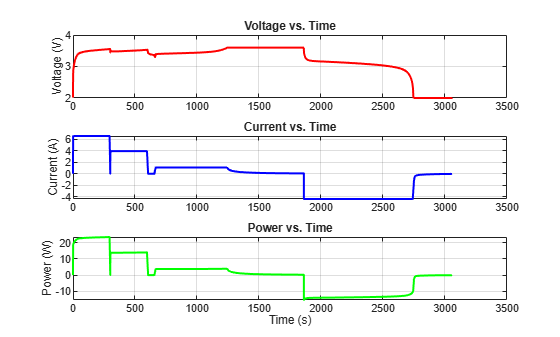

% downloads and loads data into the cycleData object
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
cycleData = data(data.Cycle_Index == 1, :);

% calculates time (final_time - initial_time)
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

% calculates power (P = I*V)
cycleData.Power = cycleData.Current.*cycleData.Voltage;

% one figure holding the three required subplots
figure;

% plots Voltage vs. Time subplot
subplot(3,1,1);
plot(cycleData.DateTime, cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
title('Voltage vs. Time');
grid on;

% plots Current vs. Time subplot
subplot(3,1,2);
plot(cycleData.DateTime, cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');
title('Current vs. Time');
grid on;

% plots Power vs. Time subplot
subplot(3,1,3);
plot(cycleData.DateTime, cycleData.Power, '-g', 'LineWidth', 1.5);
ylabel('Power (W)');
xlabel('Time (s)');
title('Power vs. Time');
grid on;


chargeData = cycleData(cycleData.Current > 0, :);

% time reset to 0 for charging period
t = chargeData.DateTime - chargeData.DateTime(1);
V = chargeData.Voltage;
I = chargeData.Current;
P = chargeData.Power;

%% fit the theoretical model
% gofTask2 is deliberately NOT called gof: Task 1 already owns a variable of
% that name, and reusing it here would overwrite the statistics Task 1 reports.
rcModel = fittype('3.6*(1-exp(-t./tau))', 'independent', 't', 'coefficients', 'tau');
[fitCurve, gofTask2] = fit(t, V, rcModel, 'StartPoint', max(t)/3, 'Lower', eps);
tau = fitCurve.tau;

%% display fitting results in table
% No semicolon and no disp(): leaving the variable unsuppressed makes the Live
% Editor render it as a formatted table rather than as plain text output.
fitResults = table(tau, gofTask2.rsquare, gofTask2.rmse, ...
    'VariableNames', {'Tau (s)','R^2','Root Mean Square Error (V)'})

fitResults = 1×3 table
    Tau (s)      R^2      Root Mean Square Error (V)
    _______    _______    __________________________

    0.22793    0.22936             0.27328          

	Get insights using Copilot


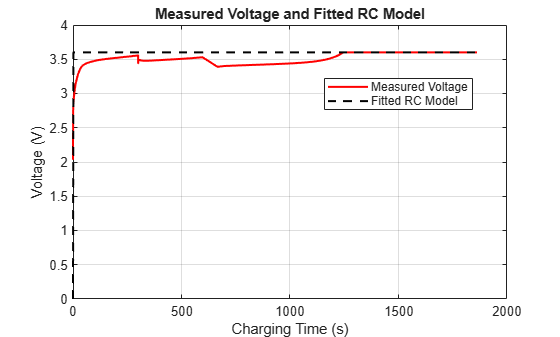


%% calculate smooth theoretical curve
tModel = linspace(min(t), max(t), 1000)';
VModel = fitCurve(tModel);

%% plot measured and theoretical voltage
figure;
plot(t, V, 'r-', tModel, VModel, 'k--', 'LineWidth', 1.5);

xlabel('Charging Time (s)');
ylabel('Voltage (V)');
title('Measured Voltage and Fitted RC Model');
legend('Measured Voltage','Fitted RC Model','Location','best');
grid on;

**Figure 2. **Voltage, current and power against time for cycle 1, on a shared time axis. The current subplot separates the cycle into its charging, resting and discharging regions, and the power subplot changes sign with it, confirming that positive current corresponds to energy entering the cell. The descending staircase in the current during charging is the multi-step constant-current profile, and each of its steps aligns with a downward step in the voltage panel.

**Figure 3. **Measured charging voltage against the fitted first-order RC model over the charging window alone. The fitted curve rises to its 3.6 V asymptote almost immediately and then runs above the measurement, which is the same behavior reported in section 1.8 and is the consequence of a single-exponential model being applied to a CC-CV charge.

**2.6  Conclusion**

**Results. **Cycle 1 spans [duration] s and separates cleanly into a charging region of [tCharge] s, a rest, and a discharging region. Terminal voltage rises from [V0] V to the 3.6 V full-charge level and then falls during discharge; current peaks at [Imax] A while charging and reaches [Imin] A while discharging; instantaneous power peaks at [Pmax] W. Fitting the RC model to the charging window returned a time constant of 0.228 s with an R-squared of 0.229 and a root-mean-square error of 0.273 V.

**What the figures show. **The three subplots change character together. Power is positive exactly where current is positive and negative exactly where current is negative, with both crossing zero at the same instant, which confirms the sign convention and the identification of the charging window. Within the charging region the current forms a descending staircase rather than holding one level, and each step down coincides with an immediate downward step in terminal voltage: the ohmic contribution falling with the current while the state of charge continues to rise. After the voltage reaches 3.6 V the current tapers and power falls away with it, which is the constant-voltage phase.

**Cross-check on Task 1. **The fit performed in this section uses a different specification from the one in Task 1, with the maximum voltage written into the model expression, a starting guess taken from the record length rather than fixed, and a different lower bound. It returns the same time constant and the same goodness-of-fit statistics. Two independently configured optimizations agreeing to this precision shows that the Task 1 result reflects the data rather than the way the solver was set up, and that the estimate is insensitive to the starting guess.

**Engineering meaning. **The figures show where the energy actually goes in time. Power is concentrated in the constant-current stages, so most of the charge is delivered early, while the constant-voltage taper occupies a large share of the elapsed time for a small share of the energy. That asymmetry is the practical reason fast-charging specifications quote a time to 80% rather than to 100%, and the area under the power curve plotted here is exactly the quantity Task 3 integrates.

# Task 3 - Matlab Calculations

## Preliminary Data

An organization of data that will be used in future calculations.

% Stage 1
s1Time = zeros([1 184]);
for i = 1 : 184
    s1Time(i) = chargeData.Step_Time(i);
end
s1V = zeros([1 184]);
for i = 1 : 184
    s1V(i) = chargeData.Voltage(i);
end
s1I = zeros([1 184]);
for i = 1 : 184
    s1I(i) = chargeData.Current(i);
end

% Stage 2
s2Time = zeros([1 90]);
for i = 1 : 90
    s2Time(i) = chargeData.Step_Time(i + 184);
end
s2V = zeros([1 90]);
for i = 1 : 90
    s2V(i) = chargeData.Voltage(i + 184);
end
s2I = zeros([1 90]);
for i = 1 : 90
    s2I(i) = chargeData.Current(i + 184);
end

% Stage 3
s3Time = zeros([1 165]);
for i = 1 : 165
    s3Time(i) = chargeData.Step_Time(i + 274);
end
s3V = zeros([1 165]);
for i = 1 : 165
    s3V(i) = chargeData.Voltage(i + 274);
end
s3I = zeros([1 165]);
for i = 1 : 165
    s3I(i) = chargeData.Current(i + 274);
end

% Stage 4
s4Time = zeros([1 171]);
for i = 1 : 171
    s4Time(i) = chargeData.Step_Time(i + 439);
end
s4V = zeros([1 171]);
for i = 1 : 171
    s4V(i) = chargeData.Voltage(i + 439);
end
s4I = zeros([1 171]);
for i = 1 : 171
    s4I(i) = chargeData.Current(i + 439);
end

## Energy Loss to Heat (Power)

Power can be used to describe the energy loss due to heat in resistors. Power is $P=I^2 *R$ where I is the current flowing through the battery and R is the battery's internal resistance. The plot Power vs. Time shows us the total power loss over the course of a stage.

Use the drop down box to select a stage.

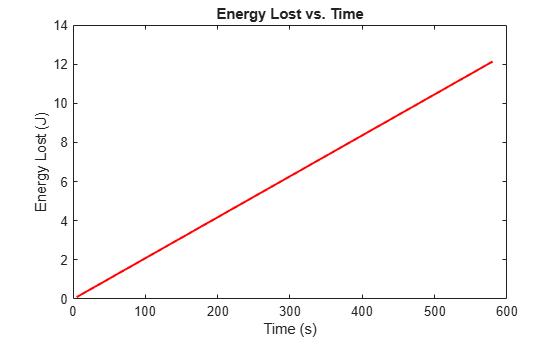

% Internal resistance
R = 0.0173;

% Calculates Power for each Stage
s1P = zeros([1 184]);
s1P(1) = s1I(1) * R;
for i = 2 : 184
    s1P(i) = s1I(i)^2 * R;
end
s2P = zeros([1 90]);
s2P(1) = s2I(1) * R;
for i = 2 : 90
    s2P(i) = s2I(i)^2 * R;
end
s3P = zeros([1 165]);
s3P(1) = s3I(1) * R;
for i = 2 : 165
    s3P(i) = s3I(i)^2 * R;
end
s4P = zeros([1 171]);
s4P(1) = s4I(1)^2 * R;
for i = 2 : 171
    s4P(i) = s4I(i) * R;
end

% Select a Stage
stage = 3;

% Stage 1
if stage == 1
    lostE = zeros([1, 184]);
    lostE(1) = s1P(1) * s1Time(1);
    for i = 2 : 184
        lostE(i) = lostE(i - 1) + (s1P(i) * (s1Time(i) - s1Time(i - 1)));
    end
    figure;
    plot(s1Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 2
elseif stage == 2
    lostE = zeros([1, 90]);
    lostE(1) = s2P(1) * s2Time(1);
    for i = 2 : 90
        lostE(i) = lostE(i - 1) + (s2P(i) * (s2Time(i) - s2Time(i - 1)));
    end
    figure;
    plot(s2Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 3
elseif stage == 3
    lostE = zeros([1, 165]);
    lostE(1) = s3P(1) * s3Time(1);
    for i = 2 : 165
        lostE(i) = lostE(i - 1) + (s3P(i) * (s3Time(i) - s3Time(i - 1)));
    end
    figure;
    plot(s3Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 4
else
    lostE = zeros([1, 171]);
    lostE(1) = s4P(1) * s4Time(1);
    for i = 2 : 171
        lostE(i) = lostE(i - 1) + (s4P(i) * (s4Time(i) - s4Time(i - 1)));
    end
    figure;
    plot(s4Time, lostE, '-r', 'LineWidth', 1.5);
end

% Plots Energy vs. Time
ylabel('Energy Lost (J)');
xlabel("Time (s)");
title('Energy Lost vs. Time');

disp("Total Energy Lost in Stage " + stage + ": " + lostE(end) + "J");

Total Energy Lost in Stage 3: 12.1316J


The first three stages all have a linear relation when comparing energy and time. Current stays nearly constant during these three stages, leading to a constant amount of energy being added to the circuit. 

Stage 4 breaks this trend and instead has an almost natural log like curve. Stage 4 contains data collected from the end of a battery being charged, so as the voltage levels off to 3.6V, current stops flowing through the battery, leading to the amount of energy lost due to internal resistance being zero once current stops.

## Total Energy

Energy can be described as the area under the power curve. We can approximate the area under the power curve by multiplying the power of the battery and the change in time together.

Use the drop down box to select a stage.

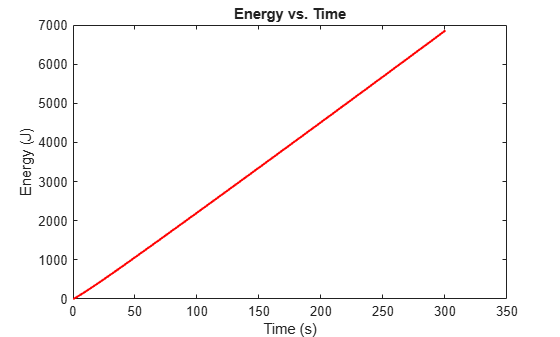

% Calculates Total Power of all Stage
P1 = s1I .* s1V;
P2 = s2I .* s2V;
P3 = s3I .* s3V;
P4 = s4I .* s4V;

% Select a Stage
stage = 1;

% Stage 1
if stage == 1
    E = zeros([1, 184]);
    E(1) = P1(1) * s1Time(1);
    for i = 2 : 184
        E(i) = E(i - 1 ) + (P1(i) * (s1Time(i) - s1Time(i - 1)));
    end
    figure;
    plot(s1Time, E, '-r', 'LineWidth', 1.5);
% Stage 2
elseif stage == 2
    E = zeros([1, 90]);
    E(1) = P2(1) * s2Time(1);
    for i = 2 : 90
        E(i) = E(i - 1 ) + (P2(i) * (s2Time(i) - s2Time(i - 1)));
    end
    figure;
    plot(s2Time, E, '-r', 'LineWidth', 1.5);
% Stage 3
elseif stage == 3
    E = zeros([1, 165]);
    E(1) = P3(1) * s3Time(1);
    for i = 2 : 165
        E(i) = E(i - 1 ) + (P3(i) * (s3Time(i) - s3Time(i - 1)));
    end
    figure;
    plot(s3Time, E, '-r', 'LineWidth', 1.5);
% Stage 4
else
    E = zeros([1, 171]);
    E(1) = P4(1) * s4Time(1);
    for i = 2 : 171
        E(i) = E(i - 1 ) + (P4(i) * (s4Time(i) - s4Time(i - 1)));
    end
    figure;
    plot(s4Time, E, '-r', 'LineWidth', 1.5);
end

% Plots Energy vs. Time
ylabel('Energy (J)');
xlabel("Time (s)");
title('Energy vs. Time');

disp("Total Energy for Stage " + stage + ": " + E(end) + "J");

Total Energy for Stage 1: 6860.7863J


Similar to the energy lost due to internal resistivity, the total energy for the first three stages have a linear relation to time. Stage 4 breaks this trend once again because as current stops flowing through the battery, the energy goes down as well.

## Change in Voltage Over Time (dv/dt)

The matlab gradient function estimates the derivative of a set of data by finding the difference between each pair of adjacent data points. We can take this data and plot dv/dt vs. Time to analyze the change in voltage over the change in time.

Use the drop down box to select a stage.

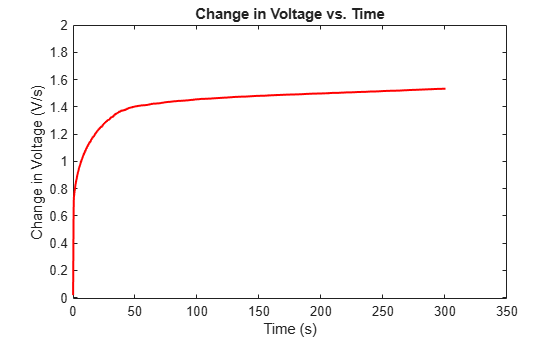

% Select a Stage
stage = 1;

% Calculates dv/dt for each Voltage Value
if stage == 1
    DV = gradient(s1V);
elseif stage == 2
    DV = gradient(s2V);
elseif stage == 3
    DV = gradient(s3V);
else
    DV = gradient(s4V);
end

totalDV =  zeros([1 numel(DV)]);
totalDV(1) = DV(1);
for i = 2 : numel(DV)
    totalDV(i) = totalDV(i - 1) + DV(i);
end

% Plots dv/dt vs t
if stage == 1
    figure;
    plot(s1Time, totalDV, '-r', 'LineWidth', 1.5);
elseif stage == 2
    figure;
    plot(s2Time, totalDV, '-r', 'LineWidth', 1.5);
elseif stage == 3
    figure;
    plot(s3Time, totalDV, '-r', 'LineWidth', 1.5);
else
    figure;
    plot(s4Time, totalDV, '-r', 'LineWidth', 1.5);
end
ylim([-0.01 2]);
% xlim([0 1500])
ylabel('Change in Voltage (V/s)');
xlabel("Time (s)");
title('Change in Voltage vs. Time');

Stage 1 has a quick jump in the beginning before leveling off, signally the fast charging of a battery in the beginning. Stage 2 and stage 3 have a much lower dv/dt because these stages are past the initial charge, leading to the increase in voltage being much slower. Stage 4 represents the end of the battery being charged, meaning it has reached its limit and so voltage stays at around 3.6V, causing dv/dt to remain around zero.

## V and t at a Specified Percent of Charge

The following code can find the voltage and time values when the battery is at a specific percentage. The time constant tau was estimated by finding the time it takes for the battery to reach 63% charged, which is approximately 1.645s.

Use the slider to change the targeted percentage. 

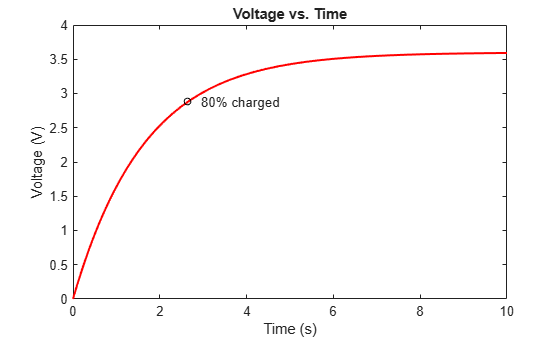

% Time Constant
tau = 1.645;

% Voltage Values
Vs = 3.6000;
Vo = 0;
Vstep = Vs + (Vo - Vs) .* exp(-(1 ./ tau) .* t);

% Desired Percent
percent = 0.8;

% Calculates the Target Voltage and Target Time
Vtarget = Vs * percent;
t_target = 0;
if percent == 1
    for i = 1 : numel(V)
        if abs(Vs - V(i)) <= 0.001
            t_target = t(i);
            break
        end
    end
else
    t_target = -tau * log((Vs * (percent - 1)) / (Vo - Vs));
end

% Plots the Vstep Function
figure;
plot(t, Vstep, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");
title('Voltage vs. Time');
hold on;

% X and Y buffer make the text appear more clearly and can
% be manually changed based on the scale of the graph
txtXBuffer = 0.3;
txtYBuffer = 0;
if percent == 1
    txtYBuffer = 0.1;
end

% Marks when the battery reaches the specified charge
txt = "% charged";
plot(t_target, Vtarget, 'ko', 'MarkerSize', 5);

if percent ~= 1
    xlim([0 10]);
end

text(t_target + txtXBuffer, Vtarget + txtYBuffer, (percent * 100) + txt);

disp("Time to reach " + (percent * 100) + "% harged: " + t_target + "s");

Time to reach 80% harged: 2.6475s


disp("Voltage at " + (percent * 100) + "% charged: " + Vtarget + "V");

Voltage at 80% charged: 2.88V


It takes about 2.6 seconds for the battery to reach about 80% charged, but it takes around 1,246 seconds, or nearly 21 minutes, to reach 100% charged. The voltage step equation is $V\left(t\right)=V_s +\left(V_o -V_s \right)e^{\frac{-t}{\tau }}$. Notice as time increases, the exponent of e grows increasingly smaller. As e decreases, the increase in voltage exponentially decreases too, explaining why it only takes 2.6 seconds to reach 80%, but nearly 21 minutes to reach 100%.

# Task 3 - Hand Calculations

## Part 1: Rate of Voltage Change

The rate of voltage change was estimated at four key charging intervals using the slope equation below. All values were obtained from charging Cycle Index 1.


$$\frac{\Delta V}{\Delta t}=\frac{V_2 -V_1 }{t_2 -t_1 }$$


### Interval 1


$$\frac{\Delta V}{\Delta t}=\frac{3\ldotp 5556803-2\ldotp 0325851}{300\ldotp 3267-0}=0\ldotp 00507146\;\frac{V}{s}$$


### Interval 2


$$\frac{\Delta V}{\Delta t}=\frac{3\ldotp 5310516-3\ldotp 4420691}{600\ldotp 5688-300\ldotp 4069}=0\ldotp 00029645\;\frac{V}{s}$$


### Interval 3


$$\frac{\Delta V}{\Delta t}=\frac{3\ldotp 5930653-3\ldotp 3886871}{1241\ldotp 4993-666\ldotp 5011}=0\ldotp 00035544\frac{V}{s}$$


### Interval 4


$$\frac{\Delta V}{\Delta t}=\frac{3\ldotp 6001358-3\ldotp 6004305}{1861\ldotp 5057-1246\ldotp 4950}=-0\ldotp 000000479\frac{V}{s}$$


%% Hand Calculated Rate of Voltage Change Results

rate1Hand = 0.00507146;
rate2Hand = 0.00029645;
rate3Hand = 0.00035544;
rate4Hand = -0.000000479;

Interval = [1; 2; 3; 4];
Rate = [rate1Hand; rate2Hand; rate3Hand; rate4Hand];

RateTable = table(Interval, Rate)

RateTable = 4×2 table
    Interval       Rate   
    ________    __________

       1         0.0050715
       2        0.00029645
       3        0.00035544
       4         -4.79e-07

	Get insights using Copilot


## Part 2: Time to 80% and 100% Charge

The maximum battery voltage provided is 3.6 V. We picked two values closest to the calculated target voltage and used those to calculate the time at which the target voltage is achieved. Since the two points are very close together, between them it is nearly a straight line. So, we can use a point-slope form equation to create the equation used below where the slope is $\frac{V_2 -V_1 }{t_2 -V_1 }$.


$$V_{\mathrm{percent}} =\frac{\mathrm{percent}}{100}\cdot V_{\max }$$



$$\begin{array}{l}
V_{80} =0\ldotp 80\cdot \left(3\ldotp 6\right)\\
V_{80} =2\ldotp 88\;V
\end{array}$$



$$\begin{array}{l}
V_{100} =1\ldotp 00\cdot \left(3\ldotp 6\right)\\
V_{100} =3\ldotp 60\;V\;
\end{array}$$


Equation used:


$$t=t_1 +\frac{V_{\mathrm{target}} -V_1 }{V_2 -V_1 }\left(t_2 -t_1 \right)$$


At $2\ldotp 88\;V$:


$$\begin{array}{l}
\left(t_1 ,V_1 \right)=\left(2\ldotp 4801\;s,\;2\ldotp 8725939\;V\right)\\
\left(t_2 ,V_2 \right)=\left(2\ldotp 6823\;s,2\ldotp 8825979\;V\right)
\end{array}$$


At $3\ldotp 60\;V$:


$$\begin{array}{l}
\left(t_1 ,V_1 \right)=\left(1241\ldotp 4993\;s,\;3\ldotp 5930653\;V\right)\\
\left(t_2 ,V_2 \right)=\left(1246\ldotp 4950\;s,3\ldotp 6004305\;V\right)
\end{array}$$


Calculations:


$$t_{80} =2\ldotp 4801+\frac{2\ldotp 88-2\ldotp 8725939}{2\ldotp 8825979-2\ldotp 8725939}\;\left(2\ldotp 6823-2\ldotp 4801\right)=2\ldotp 630\;s$$



$$t_{100} =1241\ldotp 4993+\frac{3\ldotp 60-3\ldotp 5930653}{3\ldotp 6004305-3\ldotp 5930653}\;\left(1246\ldotp 4950-1241\ldotp 4993\right)=1246\ldotp 203\;s$$


%% Hand Calculated Charging Time Results

time80Hand = 2.630;
time100Hand = 1246.203;

Charge = [80; 100];
Time = [time80Hand; time100Hand];

TimeTable = table(Charge, Time)

TimeTable = 2×2 table
    Charge     Time 
    ______    ______

      80        2.63
     100      1246.2

	Get insights using Copilot


## Part 3: Total Energy Delivered

Total energy delivered is the area under the Power vs Time curve. For the hand calculation, the charging curve was divided into four main regions and the energy in each region was approximated using its average power.

Equations used:


$$\begin{array}{l}
E\approx P_{\mathrm{avg}} \cdot \Delta t\\
E_{\mathrm{total}} \approx E_1 +E_2 +E_3 +E_4 
\end{array}$$


### Stage 1:


$$\begin{array}{l}
E_1 =\left(23\ldotp 0\right)\left(300\ldotp 3267\right)\\
E_1 =6907\ldotp 51\;J
\end{array}$$


### Stage 2:


$$\begin{array}{l}
E_2 =\left(14\ldotp 0\right)\left(300\ldotp 1619\right)\\
E_2 =4202\ldotp 27\;J
\end{array}$$


### Stage 3:


$$\begin{array}{l}
E_3 =\left(3\ldotp 8\right)\left(574\ldotp 9982\right)\\
E_3 =2184\ldotp 99\;J
\end{array}$$


### Stage 4:


$$\begin{array}{l}
E_4 =\left(0\ldotp 7\right)\left(615\ldotp 0107\right)\\
E_4 =430\ldotp 51\;J
\end{array}$$


### Total:


$$\begin{array}{l}
E_{\mathrm{total}} =6907\ldotp 51+4202\ldotp 27+2184\ldotp 99+430\ldotp 51\\
E_{\mathrm{total}} =13725\ldotp 28\;J
\end{array}$$


%% Hand Calculated Energy Results

energy1Hand = 6907.51;
energy2Hand = 4202.27;
energy3Hand = 2184.99;
energy4Hand = 430.51;

Stage = [1; 2; 3; 4];
Energy = [energy1Hand; energy2Hand; energy3Hand; energy4Hand];

EnergyTable = table(Stage, Energy)

EnergyTable = 4×2 table
    Stage    Energy
    _____    ______

      1      6907.5
      2      4202.3
      3        2185
      4      430.51

	Get insights using Copilot



totalEnergyHand = 13725.28

totalEnergyHand = 1.3725e+04

## Part 4: Resistive Energy Loss

Energy is lost because the battery has internal resistance. The electrical power dissipated through resistance is calculated using the equations shown.

Equation used:


$$\begin{array}{l}
P_{\mathrm{loss}} =I^2 R\\
E=P\cdot \Delta t\\
E_{\mathrm{loss}} \approx \left(I^2 R\right)\cdot \Delta t\\
E_{\mathrm{loss},\mathrm{total}} \approx E_{\mathrm{loss},1} +E_{\mathrm{loss},2} +E_{\mathrm{loss},3} +E_{\mathrm{loss},4} 
\end{array}$$


### Stage 1:


$$\begin{array}{l}
E_{\mathrm{loss},1} =\left({\left(6\ldotp 60\right)}^2 \cdot \;0\ldotp 017634364\right)\cdot \left(300\ldotp 3267\right)\\
E_{\mathrm{loss},1} \approx 230\ldotp 70\;J
\end{array}$$


### Stage 2:


$$\begin{array}{l}
E_{\mathrm{loss},2} =\left({\left(3\ldotp 96\right)}^2 \cdot \;0\ldotp 017634364\right)\cdot \left(300\ldotp 1619\right)\\
E_{\mathrm{loss},2} \approx 83\ldotp 01J
\end{array}$$


### Stage 3:


$$\begin{array}{l}
E_{\mathrm{loss},3} =\left({\left(1\ldotp 10\right)}^2 \cdot \;0\ldotp 017014710\right)\cdot \left(574\ldotp 9982\right)\\
E_{\mathrm{loss},3} \approx 11\ldotp 84\;J
\end{array}$$


### Stage 4:


$$\begin{array}{l}
E_{\mathrm{loss},4} =\left({\left(0\ldotp 25\right)}^2 \cdot \;0\ldotp 017014710\right)\cdot \left(615\ldotp 0107\right)\\
E_{\mathrm{loss},4} \approx 0\ldotp 65\;J
\end{array}$$


### Total:


$$\begin{array}{l}
E_{\mathrm{loss},\;\mathrm{total}} \approx 230\ldotp 70+83\ldotp 01+11\ldotp 84+0\ldotp 65\\
E_{\mathrm{loss},\;\mathrm{total}} \approx 326\ldotp 2\;J
\end{array}$$


%% Hand Calculated Resistive Energy Loss Results

loss1Hand = 230.70;
loss2Hand = 83.01;
loss3Hand = 11.84;
loss4Hand = 0.65;

Stage = [1; 2; 3; 4];
Loss = [loss1Hand; loss2Hand; loss3Hand; loss4Hand];

LossTable = table(Stage, Loss)

LossTable = 4×2 table
    Stage    Loss 
    _____    _____

      1      230.7
      2      83.01
      3      11.84
      4       0.65

	Get insights using Copilot



totalLossHand = 326.20

totalLossHand = 326.2000

## Final Summary

%% Final Hand Calculation Results

Rate1 = 0.00507146;
Rate2 = 0.00029645;
Rate3 = 0.00035544;
Rate4 = -0.000000479;
Time80 = 2.630;
Time100 = 1246.203;
TotalEnergy = 13725.28;
TotalLoss = 326.20;

FinalResults = table(Rate1, Rate2, Rate3, Rate4, Time80, Time100, TotalEnergy, TotalLoss)

FinalResults = 1×8 table
      Rate1        Rate2         Rate3         Rate4      Time80    Time100    TotalEnergy    TotalLoss
    _________    __________    __________    _________    ______    _______    ___________    _________

    0.0050715    0.00029645    0.00035544    -4.79e-07     2.63     1246.2        13725         326.2  

	Get insights using Copilot


## Task 4: CC-CV phase analysis and charging profile comparison

This task analyzes the battery charging profile using a constant-current/constant-voltage (CC-CV) charging model. The charging cycle is divided into two phases: the constant-current (CC) phase and the constant-voltage (CV) phase.

The analysis has three main goals:

- Identify the transition between the CC and CV phases.

- Fit an exponential model to each phase.

- Compare the power, energy, charge, and estimated efficiency of the two phases.

## Task 4.1: Identify the CC and CV Regions

A CC-CV charger operates in two stages. During the constant-current (CC) phase, the charging current remains approximately constant while the battery voltage increases. Once the battery voltage approaches the charger's voltage limit, the charger transitions to the constant-voltage (CV) phase.

During the CV phase, the voltage is maintained near the set point while the charging current decreases.

The following code isolates the charging portion of Cycle 1 and identifies the time at which the transition from CC to CV occurs. The transition is defined as the first point where the battery voltage reaches 99.9% of the 3.6 V set point.

The transition is then checked using the voltage and current rates of change. During CC charging, the voltage should be increasing, while during CV charging the voltage should remain approximately constant and the current should decrease.

%% Task 4.1: ITask 4.1: Identify the CC and CV Regions
% A CC-CV charger works in two stages. First it holds the CURRENT steady and
% lets the voltage climb (constant current). Once the voltage reaches the
% cell's limit it holds the VOLTAGE steady instead and lets the current fall
% away (constant voltage). This section finds the instant where that handover
% happens, and confirms it two independent ways: the voltage stops rising, and
% the current starts falling.

% --- load the dataset (the table it creates is called 'data') ------------
dataFile = matlab.internal.examples.downloadSupportFile( ...
    "predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

Vset = 3.6;                                  % voltage the charger holds in CV, V

% --- keep one cycle, then keep only the part where the cell is charging --
% Positive current means current flowing INTO the cell, i.e. charging.
cyc        = data(data.Cycle_Index == 1, :);
cyc.Time_s = seconds(cyc.DateTime - cyc.DateTime(1));   % timestamps -> seconds
chg        = cyc(cyc.Current > 0, :);

t4 = chg.Time_s - chg.Time_s(1);             % s, restart the clock at 0
V4 = chg.Voltage;                            % V, terminal voltage
I4 = chg.Current;                            % A, charging current
P4 = V4 .* I4;                               % W, instantaneous power

% --- how fast is the voltage changing? ----------------------------------
% gradient() is a numerical derivative. Passing t4 as the second argument
% tells it the samples are not evenly spaced in time.
dVdt = gradient(V4, t4);                     % V/s

% --- find the CC -> CV handover -----------------------------------------
% The first sample where the voltage has essentially reached the set point.
% Everything before it is CC, everything from it onward is CV.
kCV = find(V4 >= 0.999*Vset, 1);             % index of the handover
tCV = t4(kCV);                               % time of the handover, s
iCC = 1:kCV;                                 % row indices of the CC region
iCV = kCV:numel(t4);                         % row indices of the CV region

% --- report the split and the two confirmations -------------------------
fprintf('CC region : %.1f s to %.1f s (%d samples)\n', t4(1),   t4(kCV), numel(iCC));

CC region : 0.0 s to 1246.5 s (440 samples)


fprintf('CV region : %.1f s to %.1f s (%d samples)\n', t4(kCV), t4(end), numel(iCV));

CV region : 1246.5 s to 1861.5 s (173 samples)


fprintf('mean dV/dt in CC : %+.3e V/s   (voltage rising, so expect > 0)\n', mean(dVdt(iCC)));

mean dV/dt in CC : +1.104e-01 V/s   (voltage rising, so expect > 0)


fprintf('mean dV/dt in CV : %+.3e V/s   (voltage held, so expect ~ 0)\n',   mean(dVdt(iCV)));

mean dV/dt in CV : +4.357e-06 V/s   (voltage held, so expect ~ 0)


fprintf('mean dI/dt in CV : %+.3e A/s   (current tapering, so expect < 0)\n', ...
        (I4(end) - I4(kCV))/(t4(end) - t4(kCV)));

mean dI/dt in CV : -1.528e-03 A/s   (current tapering, so expect < 0)


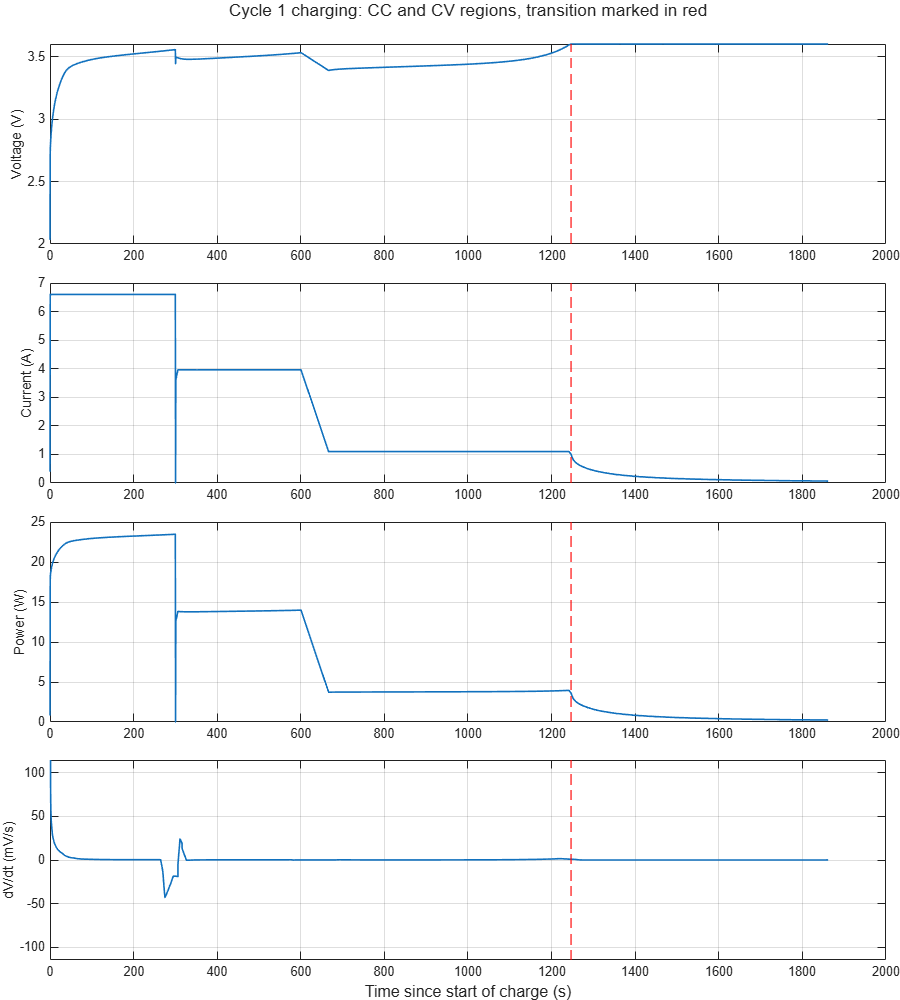


% --- figure: voltage, current, power and dV/dt on one shared time axis ---
% Note on the dV/dt panel: two moments in the record have derivatives about a
% thousand times bigger than everything else. One is the instant the charger
% connects; the other is where the charger first steps the current down, which
% drops the terminal voltage through the cell's internal resistance. Left to
% autoscale, those two spikes squash the rest of the curve flat onto zero, so
% the y-limits below are taken from the data AFTER the first 20 s instead.
dVdt_mV = dVdt*1000;                                  % mV/s, easier to read
tail    = sort(abs(dVdt_mV(t4 > 20)));                % sorted, spikes excluded
lim     = tail(round(0.99*numel(tail)));              % 99th percentile

figure('Position',[100 100 900 1000])
tl41 = tiledlayout(4,1,'TileSpacing','tight','Padding','tight');

nexttile; plot(t4, V4, 'LineWidth',1.2); ylabel('Voltage (V)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, I4, 'LineWidth',1.2); ylabel('Current (A)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, P4, 'LineWidth',1.2); ylabel('Power (W)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, movmean(dVdt_mV,15), 'LineWidth',1.2); ylabel('dV/dt (mV/s)')
grid on; xline(tCV,'--r','LineWidth',1.2); ylim([-1.5*lim 1.5*lim])

xlabel(tl41,'Time since start of charge (s)')
title(tl41,'Cycle 1 charging: CC and CV regions, transition marked in red')

**CC-CV Charging Profile**

The figure above shows the battery voltage, charging current, instantaneous power, and voltage rate of change throughout the charging cycle. The red vertical line marks the identified CC-to-CV transition.

During the CC phase, the charging current remains relatively steady while the battery voltage increases. After the transition, the voltage approaches the 3.6 V set point and the charging current begins to decrease, indicating the CV phase.

## Task 4.2: Fit Each Charging Phase

The CC and CV phases have different charging behaviors, so each phase is modeled separately.

During the CC phase, the battery voltage increases toward the voltage set point. This behavior is modeled using an exponential charging equation:


$$V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\tau }} \right)$$


where $\tau$ is the time constant of the voltage response.

During the CV phase, the voltage is maintained near the set point while the charging current decreases. The current is modeled using an exponential decay:


$$I\left(t\right)=I_0 e^{-\frac{t}{\tau_I }} +I_{\infty }$$


where $I_0$ is the initial current, $\tau_I \;$is the current-decay time constant, and $I_{\infty }$ is the current approached as charging continues.

The following code fits these models to the measured CC and CV data and calculates the goodness of fit using $R^2$ and RMSE.

%% Task 4.2: Fit each phase separately
% Each phase has its own characteristic curve. In CC the voltage rises towards
% the set point like a charging capacitor, so the Task 1 exponential applies.
% In CV the voltage is fixed and the CURRENT decays exponentially instead, so
% we fit a decay to the current. Both fits return a time constant, tau, which
% is the time taken to complete about 63% of the change.

% --- CC phase: exponential voltage rise (the Task 1 model) --------------
tCC = t4(iCC);
VCC = V4(iCC);
ftV = fittype('Vm*(1 - exp(-t/tau))', 'problem','Vm', 'independent','t');
[fitCC, gofCC] = fit(tCC, VCC, ftV, 'problem', Vset, ...
                     'StartPoint', max(tCC)/3, 'Lower', 1e-6);

% --- CV phase: exponential current decay --------------------------------
% Time restarts at the handover so the fit measures the decay from its own
% starting point. Iinf is the level the current settles towards.
% The coefficient names are listed explicitly because MATLAB otherwise sorts
% them alphabetically, which would mismatch the StartPoint values below.
tCV_rel = t4(iCV) - tCV;
ICV     = I4(iCV);
ftI = fittype('I0*exp(-t/tauI) + Iinf', 'independent','t', ...
              'coefficients', {'I0','tauI','Iinf'});
[fitCV, gofCV] = fit(tCV_rel, ICV, ftI, ...
                     'StartPoint', [max(ICV) max(tCV_rel)/3 0], ...
                     'Lower', [0 1e-6 -Inf]);

% --- results ------------------------------------------------------------
PhaseFits = table(["CC voltage rise"; "CV current decay"], ...
    [fitCC.tau; fitCV.tauI], [gofCC.rsquare; gofCV.rsquare], [gofCC.rmse; gofCV.rmse], ...
    'VariableNames', {'Phase','tau_s','R2','RMSE'})

PhaseFits = 2×4 table
          Phase            tau_s        R2         RMSE  
    __________________    _______    ________    ________

    "CC voltage rise"     0.22794    0.074269     0.32241
    "CV current decay"     89.755     0.97894    0.024707

	Get insights using Copilot


**Fit Results**

The table above summarizes the fitted time constant, (R^2), and RMSE for each charging phase.

The time constant describes how quickly the voltage or current approaches its final value. (R^2) indicates how well the model describes the measured data, with values closer to 1 indicating a stronger fit. RMSE represents the typical difference between the measured values and the fitted model.

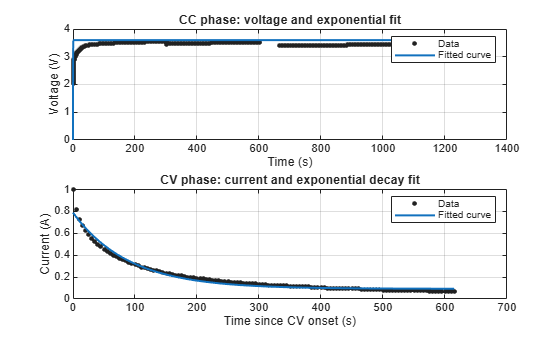

figure
subplot(2,1,1)
plot(fitCC, tCC, VCC)                        % plots the data and the fit together
xlabel('Time (s)'); ylabel('Voltage (V)'); grid on
title('CC phase: voltage and exponential fit')

subplot(2,1,2)
plot(fitCV, tCV_rel, ICV)
xlabel('Time since CV onset (s)'); ylabel('Current (A)'); grid on
title('CV phase: current and exponential decay fit')

## Task 4.3: Power & Energy Comparison

The final part of the analysis compares the power and energy delivered during the CC and CV phases.

Instantaneous charging power is calculated from:


$$P\left(t\right)=V\left(t\right)I\left(t\right)$$


The energy delivered during each phase is determined by integrating power over time:


$$E=\int P\left(t\right)\;\mathrm{dt}$$


Because the battery measurements are discrete, the trapezoidal numerical integration method is used.

The estimated resistive energy loss is also calculated using the battery's internal resistance:


$$P_{\mathrm{loss}} =I^{2R}$$


This allows the CC and CV phases to be compared based on energy delivered, average power, charge delivered, estimated Joule losses, and efficiency.

%% Task 4.3: Power and energy delivered in each phase
% Energy is the area under the power curve, so trapz() (the trapezoidal rule)
% integrates power over time to get joules. Doing this separately for the two
% regions shows where the charge actually goes, and comparing each phase's
% Joule loss against the energy it delivered shows where charging is most
% efficient. Loss is I^2*R, so it grows with the SQUARE of the current:
% halving the current cuts the waste to a quarter.

% Internal resistance measured in the dataset, used for the loss estimate.
Rint = mean(chg.Internal_Resistance, 'omitnan');     % ohm

dur   = [t4(kCV)-t4(1);           t4(end)-t4(kCV)];                         % s
E     = [trapz(t4(iCC), P4(iCC)); trapz(t4(iCV), P4(iCV))];                 % J
Q_Ah  = [trapz(t4(iCC), I4(iCC)); trapz(t4(iCV), I4(iCV))]/3600;            % Ah
Eloss = [trapz(t4(iCC), I4(iCC).^2*Rint); trapz(t4(iCV), I4(iCV).^2*Rint)]; % J
Pmean = E./dur;                                      % W, average power
eff   = 100*(E - Eloss)./E;                          % %, energy reaching the cell
share = 100*E/sum(E);                                % %, split of the total

PhaseEnergy = table(["CC";"CV"], dur, E, E/3600, share, Pmean, Q_Ah, Eloss, eff, ...
    'VariableNames', {'Phase','Duration_s','Energy_J','Energy_Wh','EnergyShare_pct', ...
                      'MeanPower_W','Charge_Ah','JouleLoss_J','Efficiency_pct'})

PhaseEnergy = 2×9 table
    Phase    Duration_s    Energy_J    Energy_Wh    EnergyShare_pct    MeanPower_W    Charge_Ah    JouleLoss_J    Efficiency_pct
    _____    __________    ________    _________    _______________    ___________    _________    ___________    ______________

    "CC"       1246.5        13791       3.8307          96.97            11.064        1.1032        328.88          97.615    
    "CV"       615.01       430.96      0.11971         3.0303           0.70073       0.03325       0.67329          99.844    

	Get insights using Copilot


**Energy and Efficiency Results**

The table above summarizes the charging characteristics of the CC and CV phases. The results include the duration of each phase, energy delivered, percentage of total energy, average power, charge delivered, estimated Joule loss, and estimated efficiency.

These values can be used to determine which phase contributes the most energy, which phase operates more efficiently, and which phase requires the most time.

% Pick out the answers rather than leaving them to be read off the table.
phaseName = ["CC","CV"];
[~, kEnergy] = max(E);                               % which phase delivered more
[~, kEff]    = max(eff);                             % which phase wasted less
[~, kLong]   = max(dur);                             % which phase took longer
fprintf('internal resistance used     : %.4f ohm\n', Rint);

internal resistance used     : 0.0173 ohm


fprintf('most energy delivered during : %s (%.1f %% of %.1f J)\n', ...
        phaseName(kEnergy), share(kEnergy), sum(E));

most energy delivered during : CC (97.0 % of 14221.6 J)


fprintf('most efficient phase         : %s (%.2f %% vs %.2f %%)\n', ...
        phaseName(kEff), eff(kEff), eff(3-kEff));

most efficient phase         : CV (99.84 % vs 97.62 %)


fprintf('longest phase                : %s (%.1f %% of the time)\n', ...
        phaseName(kLong), 100*dur(kLong)/sum(dur));

longest phase                : CC (67.0 % of the time)


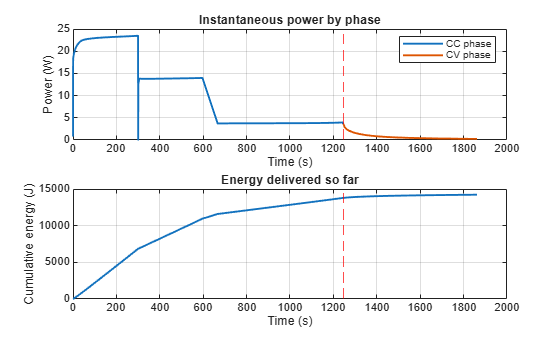


figure
subplot(2,1,1)
plot(t4(iCC), P4(iCC), t4(iCV), P4(iCV), 'LineWidth',1.4)
xline(tCV,'--r'); xlabel('Time (s)'); ylabel('Power (W)'); grid on
legend('CC phase','CV phase'); title('Instantaneous power by phase')

subplot(2,1,2)
plot(t4, cumtrapz(t4, P4), 'LineWidth',1.4)          % running total of energy
xline(tCV,'--r'); xlabel('Time (s)'); ylabel('Cumulative energy (J)'); grid on
title('Energy delivered so far')

## Task 4 Summary

This analysis separates the battery charging cycle into its constant-current and constant-voltage phases. The CC-to-CV transition is identified from the battery voltage and verified using the changes in voltage and current.

Each phase is modeled independently using an exponential function, allowing the charging dynamics to be characterized using time constants and goodness-of-fit measurements. Finally, power and energy calculations are used to compare how the two phases contribute to the overall charging process.

The numerical results and figures generated above provide the basis for comparing the behavior and efficiency of the CC and CV charging phases.

## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

The analysis shows how the battery's charging behavior changes between the constant-current (CC) and constant-voltage (CV) phases. During the CC phase, the charging current remains relatively steady while the battery voltage increases toward the 3.6 V voltage limit. Once the voltage reaches the set point, the charger transitions to the CV phase, where the voltage is maintained while the charging current gradually decreases.

Separating the charging profile into these two phases allows the battery's behavior to be analyzed more accurately than using one model for the entire charging cycle. The exponential fits provide time constants that describe how quickly the voltage and current respond during each phase. The power and energy calculations also show how energy is distributed throughout the charging process and provide an estimate of the energy lost through the battery's internal resistance.

These results are useful from an engineering perspective because understanding the CC-CV transition can help engineers evaluate charging performance, estimate charging time, reduce energy losses, and design charging systems that operate the battery safely and efficiently.

What are some limitations of your work?

There are several limitations to this analysis. The model uses data from a single charging cycle, so the results may not represent the battery's behavior over many cycles or under different operating conditions. The CC-to-CV transition is also identified using a fixed voltage threshold of 99.9% of the set point, which is an approximation of the actual transition used by a real battery charger.

The exponential models are simplified representations of the battery's behavior. Real batteries have nonlinear electrochemical behavior that can be affected by temperature, state of charge, aging, and changing internal resistance. Additionally, the energy-loss calculation assumes a constant average internal resistance, even though the battery's internal resistance can change during charging.

What are practical next steps?

A practical next step would be to repeat the analysis across multiple charging cycles and compare the results to determine whether the fitted time constants, energy distribution, and efficiency remain consistent. The analysis could also be repeated at different temperatures, charging rates, or battery aging levels to study how operating conditions affect the charging profile.

A more advanced model could incorporate a changing internal resistance and additional battery parameters to better represent the battery's electrochemical behavior. These improvements could make the model more useful for predicting charging performance and evaluating battery-management or charging-system designs.